# Adding Useful Forces to your 6DOF UAV Model

## Topic

This LiveScript shows you how to add some simple forces to your 6DOF UAV model to make it more useful.

## Motivation

In the last lesson,  you developed a full 6 DOF model with forces as a constant input.   In this lesson you will create a few forces to make the results more meaningful.   As with the 3 DOF model, this will include gravity and drag as well as a simple feed-forward force and a PD force for altitude.  This is enough for a very simple hover model and is a good place to start..    

## Learning Objective

You will learn to add four useful forces.  Care needs to be taken as you pay attention to the frame of reference, whether you are using the Inertial Flat-Earth Frame or the UAV Body Frame.    You will also learn how to formulate these forces in terms of the state variables you are using in your model.

## Lesson

### Adding Useful Forces

In previous lessons you added a few useful forces to your 3 DOF models to make them more interesting and useful.  You are ready to do this now with your 6 DOF model.   The forces are: 

- Gravity

- Feed Forward

- Drag

- PD Control

#### Gravity

The gravitational force is written in the Inertial Flat-Earth Frame.   In our coordinate system, the gravitational force points in the positive-z direction.


$$F_{\textrm{gravity}} =\textrm{mg}{\hat{a} }_z$$


#### Feed Forward

The feed forward term will be implemented by the UAV propellers in the Body Reference Frame.   You will spin up the propellers to a constant speed with the purpose to apply sufficient thrust so that when the UAV is level to the flat Earth, it hovers;  this can be done in either frame and it is easiest to implement in the Body Frame.    When the UAV is level to the flat Earth, then the rotation matrix is an identity matrix.  More generally, in the Inertial Flat-Earth Frame, it is written.


$$F_{\textrm{fwd}} =R^T \left(\theta ,\phi ,\psi \right)\left\lbrack \begin{array}{c}
0\\
0\\
f_{\textrm{fwd}} 
\end{array}\right\rbrack$$


#### Drag

When you introduced drag in the 3DOF model, you wrote it in terms of the inertial reference frame.  Now it will be more convenient to write it in terms of the velocity in the body reference frame.  This is because the coefficient of drag is associated with the body geometry.


$$F_{\textrm{drag}} ={-k}_d v^2 {\hat{a} }_v$$


To accomplish the change in your model, you start with the relationship between velocity in the different frames.


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack =R^T \left(\theta ,\phi ,\psi \right)\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack$$
     

The magnitude of the velocity is constant irrespective of the frame of reference, so

   
$$\sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack =R^T \left(\theta ,\phi ,\psi \right)\sqrt{{\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack$$


and, so with gravity and drag, the forces become


$$F_{\textrm{drag}} =-k_d R^T \left(\theta ,\phi ,\psi \right)\sqrt{{\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack$$


### PD Controller for Altitude

You implemented your first PD controller, with the 3 DOF model, with simple terms, a term proportional to the difference between your UAV altitude and its desired altitude, and a term proportional to your UAV current velocity and its desired velocity.   With the 6 DOF model, the first term remains the same.


$$F_p =k_p \left\lbrack \begin{array}{c}
0\\
0\\
\left(z_{\textrm{desired}} -z\right)
\end{array}\right\rbrack$$
 

For the velocity term of our simple controller, we start with the velocity in the Body Frame, transform to the Inertial Flat-Earth Frame, and then consider the $v_z$, component.   And so,


$$F_v ={-k}_v \left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack R^T \left(\theta ,\phi ,\psi \right)\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack$$
 

#### Total Applied Force

The total applied force for this model is the sum of these and is used in the equations of motion:


$$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack +\frac{1}{m}F_{\textrm{Total}}$$


with 


$$F_{\textrm{Total}} =F_{\textrm{gravity}} +F_{\textrm{fwd}} +F_{\textrm{drag}} +F_p +F_v$$


### Implementation in Body Reference Frame  

The forces applied to create this control are generated by the propellers on the UAV.   It is therefore useful to write them in terms of the body reference frame.    In fact, it will be convenient to write all of the forces in the Body Reference Frame.   So here the forces are written as a rotation matrix multiplied by the force in the Body Reference.


$$\left\lbrack \begin{array}{c}
F_x^{\textrm{Total}} \\
F_y^{\textrm{Total}} \\
F_z^{\textrm{Total}} 
\end{array}\right\rbrack =R^T \left(\theta ,\phi ,\psi \right)\left\lbrace R\left(\theta ,\phi ,\psi \right)\left\lbrack \begin{array}{c}
0\\
0\\
\textrm{mg}
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
f_{\textrm{fwd}} 
\end{array}\right\rbrack -k_d \sqrt{{\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack +k_p R\left(\theta ,\phi ,\psi \right)\left\lbrack \begin{array}{c}
0\\
0\\
z_{\textrm{desired}} -z
\end{array}\right\rbrack {-k}_v R\left(\theta ,\phi ,\psi \right)\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack R^T \left(\theta ,\phi ,\psi \right)\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack \right\rbrace$$


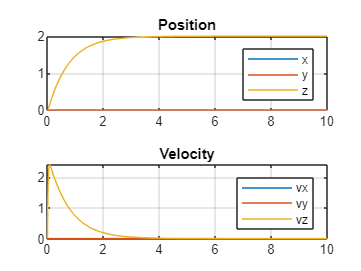

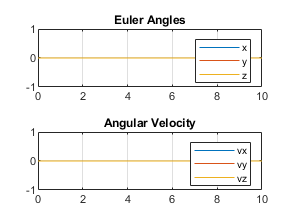

clear;
addpath('utils');
params=sys_params;
[w0,fxyz,mxyz,~,~,~,~,~]=initializeParameters;


kd=0.04;                 % Drag coefficient kd   
kp=4;                   % Proportional Control coefficient kp
kv=3;                   % Differential Control coefficient kv
zdesired=2;            % Desired Altitude

ff=-params.mass * params.gravity;

tmax=10;
tspan=[0,tmax];

systemDerivative=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired);
[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output6dof(ts,ws)

## Conclusion

In this lesson, a few simple forces to your 6 DOF models to make it more interesting and useful.   The forces are: 

- Gravity

- Feed Forward

- Drag

- PD Control

The PD Control was presented simply so that you can begin to develop some intuition about reading the output.   It is very simple but allows you to bring your UAV to achieve a desired altitude - essentially a hover.

## Exercises:  Enhance your 6DOF UAV Model with drag and a PD altitude controller

At this point, you can set up your own equations of motion and use a solver such as ode45 to get the results of the equations of motion.   You will also want to display all twelve states.

**Part A.**   Prepare a subfunction that represents the updated equations of motion.

- Set External Forces and Moments from your prior exercise to zero, but don't remove them, as they will be used again later.

- Add a coefficient for aerodynamic drag to the function input list

- Add a set of PD (proportional, derivative) coefficients to the function input list

- Add a desired altitude (z position) to the function input list

- Add the drag and PD control to your equations of motion

**Part B.**  Create a new parametric output function so that you can display all 6 degrees of freedom and their first derivatives.

% Your code goes here.



